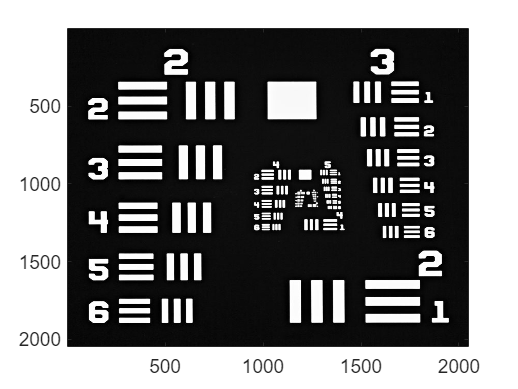

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 10;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
dx = 6.513*mm/(Nx*M); 
dy = dx;

% Longitud de Onda de iluminación
lambda = 720*nm;

% Apertura númerica
AN = 0.25;

%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;
 

%Leer imagenes 

tamanoImagen = 2048;

estrella = 'SiemensStar_2048_AD.png';
usaf = 'usaf.jpg';

nombre = usaf;

if strcmp(nombre,estrella) 
    tamanoImagen = 2048;
elseif strcmp(nombre,usaf)
    tamanoImagen = 780;
end 

Imagen1 = imread(nombre);
Imagen1 = imresize(im2gray(Imagen1), Nx/tamanoImagen);
% Imagen2 = imread(nombre);
% Imagen2 = imresize(im2gray(Imagen2), Nx/tamanoImagen);
% Imagen3 = imread(nombre);
% Imagen3 = imresize(im2gray(Imagen3), Nx/tamanoImagen);

% Imagen1 = filtroCircular([Nx/2 Ny/2], 100, [Nx Ny]);
Imagen2 = filtroCuadrado([(Nx/2)-100 Ny/2], [100 100], [Nx Ny]);
Imagen3 = filtroCircular([(Nx/2)+100 Ny/2], 300, [Nx Ny]);

Imagen1 = im2gray(im2double(Imagen1));
%Imagen1 = ~Imagen1;
Imagen2 = im2gray(im2double(Imagen2));
%Imagen2 = ~Imagen2;
Imagen3 = im2gray(im2double(Imagen3));
%Imagen3 = ~Imagen3;


imagesc(Imagen1)
colormap("gray")

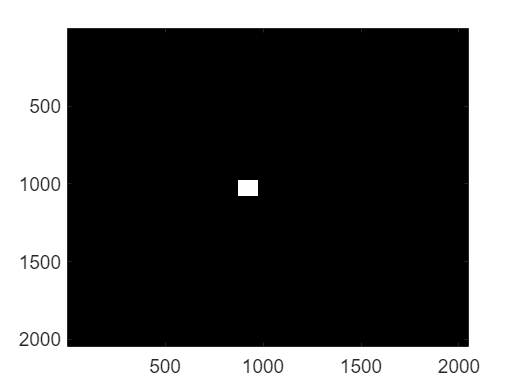

imagesc(Imagen2)
colormap("gray")

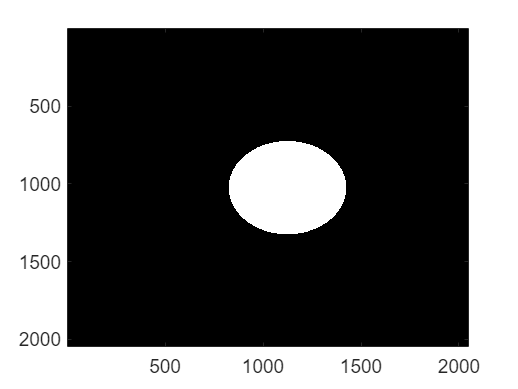

imagesc(Imagen3)
colormap("gray")


%Proceso para un microscopio de un foton. 

%Se usara un indicador para elegir el plano focal, si el
%que contiene a la imagen 1, 2 o 3. 

indicador = 1; 
transform = 2;

zlim = Nx*dx^2/lambda

zlim = 2.8767e-04

cadena = "primera imagen microscopio"

cadena1 = "figura2"

cadena2 = "figura3"

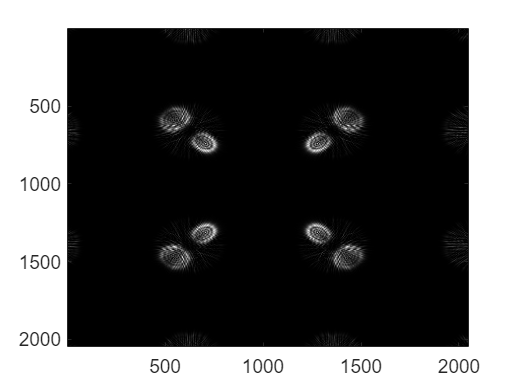


if indicador == 1
    %La imagen uno se encontrara en foco, por lo que no deberá hacerse
    %propagación inicial. 
    [salidafocal, observacion1, pupila] = microscopio(Imagen1,M,f2,AN,Nx,Ny,dx,dy,lambda);
    cadena = "primera imagen microscopio"
    salidafocalmod = (abs(salidafocal)).^2;
    imagesc(salidafocalmod)
    %La imagen dos se encontrara fuera de foco por 10 mm, por lo que
    %primero se debe propagar hasta el plano focal. En este caso usaremos
    %(Definir que propagación usar). 

    distIm2 = 400*um;

    if transform == 1
        Imagen2Prop = espectroAngular(Imagen2, dx,dy,Nx,Ny,distIm2,lambda);
    else
        Imagen2Prop = transformadaFresnel(Imagen2, dx,dy,Nx,Ny,distIm2,lambda);
    end

    %La imagen tres se encontrara fuera de foco por 20mm, por lo que primero
    %se debe propagar hasta el plano focal. 

    
    cadena1 = "figura2"
    Imagen2Propmod = (abs(Imagen2Prop)).^2;
    [salida2, observacion2, pupila2] = microscopio(Imagen2Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida2mod = (abs(salida2)).^2;
    imagesc(Imagen2Propmod)
    imagesc(salida2mod)

    distIm3 = 800*um;

    if transform == 1
        Imagen3Prop = espectroAngular(Imagen3, dx,dy,Nx,Ny,distIm3,lambda);
    else 
        Imagen3Prop = transformadaFresnel(Imagen3, dx,dy,Nx,Ny,distIm3,lambda);
    end

    cadena2 = "figura3"
    Imagen3Propmod = (abs(Imagen3Prop)).^2;
    [salida3, observacion3, pupila3] = microscopio(Imagen3Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida3mod = (abs(salida3)).^2;
    imagesc(Imagen3Propmod)
    imagesc(salida3mod)

    
    colormap("gray")
    
elseif indicador == 2
    %La imagen dos se encontrara en foco, por lo que no deberá hacerse
    %propagación inicial. 
    [salidafocal, observacion2, pupila] = microscopio(Imagen2,M,f2,AN,Nx,Ny,dx,dy,lambda);
    cadena = "primera imagen microscopio"
    salidafocalmod = (abs(salidafocal)).^2;
    imagesc(salidafocalmod)
    %La imagen dos se encontrara fuera de foco por 10 mm, por lo que
    %primero se debe propagar hasta el plano focal. En este caso usaremos
    %(Definir que propagación usar). 

    distIm1 = -400*um;
    
    if transform == 1
        Imagen1Prop = espectroAngular(Imagen1, dx,dy,Nx,Ny,distIm1,lambda);
    else 
        Imagen1Prop = transformadaFresnel(Imagen1, dx,dy,Nx,Ny,distIm1,lambda);
    end


    %La imagen tres se encontrara fuera de foco por 20mm, por lo que primero
    %se debe propagar hasta el plano focal. 

    
    cadena1 = "figura2"
    Imagen1Propmod = (abs(Imagen1Prop)).^2;
    [salida1, observacion1, pupila1] = microscopio(Imagen1Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida1mod = (abs(salida1)).^2;
    imagesc(Imagen1Propmod)
    imagesc(salida1mod)

    distIm3 = 400*um;

    if transform == 1
        Imagen3Prop = espectroAngular(Imagen3, dx,dy,Nx,Ny,distIm3,lambda);
    else 
        Imagen3Prop = transformadaFresnel(Imagen3, dx,dy,Nx,Ny,distIm3,lambda);
    end
    
    cadena2 = "figura3"
    Imagen3Propmod = (abs(Imagen3Prop)).^2;
    [salida3, observacion3, pupila3] = microscopio(Imagen3Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida3mod = (abs(salida3)).^2;
    imagesc(Imagen3Propmod)
    imagesc(salida3mod)

    
    colormap("gray")
else
    %La imagen tres se encontrara en foco, por lo que no deberá hacerse
    %propagación inicial. 
    [salidafocal, observacion3, pupila] = microscopio(Imagen3,M,f2,AN,Nx,Ny,dx,dy,lambda);
    cadena = "primera imagen microscopio"
    salidafocalmod = (abs(salidafocal)).^2;
    imagesc(salidafocalmod)
    %La imagen dos se encontrara fuera de foco por 10 mm, por lo que
    %primero se debe propagar hasta el plano focal. En este caso usaremos
    %(Definir que propagación usar). 

    distIm2 = -400*um;
    

    if transform == 1
        Imagen2Prop = espectroAngular(Imagen2, dx,dy,Nx,Ny,distIm2,lambda);
    else
        Imagen2Prop = transformadaFresnel(Imagen2, dx,dy,Nx,Ny,distIm2,lambda);
    end

    %La imagen tres se encontrara fuera de foco por 20mm, por lo que primero
    %se debe propagar hasta el plano focal. 

    
    cadena1 = "figura2"
    Imagen2Propmod = (abs(Imagen2Prop)).^2;
    [salida2, observacion2, pupila2] = microscopio(Imagen2Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida2mod = (abs(salida2)).^2;
    imagesc(Imagen2Propmod)
    imagesc(salida2mod)

    distIm1 = -800*um;

    if transform == 1
        Imagen1Prop = espectroAngular(Imagen1, dx,dy,Nx,Ny,distIm1,lambda);
    else 
        Imagen1Prop = transformadaFresnel(Imagen1, dx,dy,Nx,Ny,distIm1,lambda);
    end
    
    cadena2 = "figura3"
    Imagen1Propmod = (abs(Imagen1Prop)).^2;
    [salida1, observacion1, pupila1] = microscopio(Imagen1Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);
    salida1mod = (abs(salida1)).^2;
    imagesc(Imagen1Propmod)
    imagesc(salida1mod)

    
    colormap("gray")
end

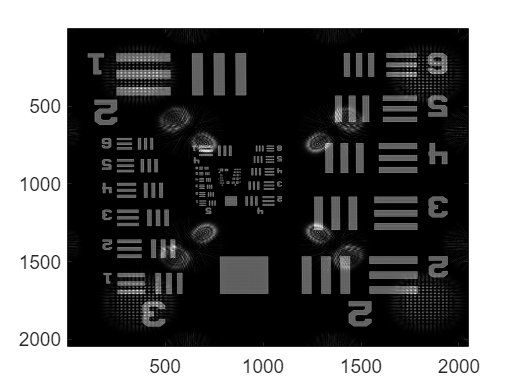


%normalización

observacion1 = (observacion1-min(observacion1,[],"all"))./(max(observacion1,[],"all")-min(observacion1,[],"all"));

observacion2 = (observacion2-min(observacion2,[],"all"))./(max(observacion2,[],"all")-min(observacion2,[],"all"));

observacion3 = (observacion3-min(observacion3,[],"all"))./(max(observacion3,[],"all")-min(observacion3,[],"all"));

superposicionFinal = observacion1+observacion2+observacion3;
imagesc((superposicionFinal))